# Fourier Transform

- generate a multispectral signal with noise

sample_rate = 1024; %hz
N = sample_rate*2; %number of samples
t = (0:N-1)/sample_rate; %time vector

%create some random frequencies and amplitudes
freqs = [ floor(1+30*rand(3,1)')]; 
amplitudes = zeros(size(freqs));
signal = zeros(size(t));

for i=1:length(freqs)
    amplitudes(i) = randi(6);
    signal = signal + amplitudes(i)*sin(2*pi*freqs(i)*t);  %give some random amplitude
end

noisy = signal + randn(size(signal))*5;

- create strings for annotation

str1 = sprintf('freq: %d, amplitude: %d', freqs(1), amplitudes(1));
str2 = sprintf('freq: %d, amplitude: %d', freqs(2), amplitudes(2));
str3 = sprintf('freq: %d, amplitude: %d', freqs(3), amplitudes(3));

## Plot the true and noisy signals

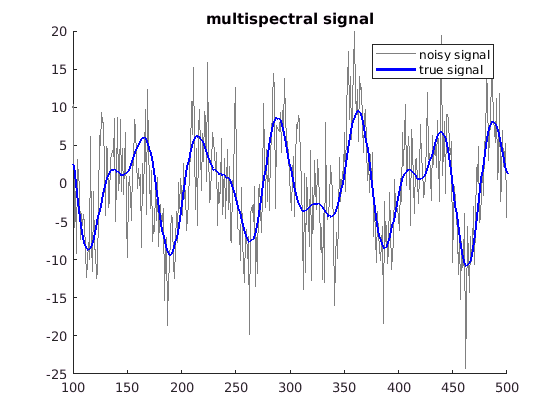

figure(1); clf;
hold on;
noisy_plot = plot(noisy);
set(noisy_plot, 'color', [.5 .5 .5]);
true_plot = plot(signal, 'b', 'linew', 2);
xlim([100 500]);
title("multispectral signal");
legend(["noisy signal", "true signal"]);
hold off;

## Apply FFT

signal_fft = fft(noisy);
signal_amp = 2*abs(signal_fft)/N;
hz_vals = linspace(0,sample_rate/2, floor(N/2)+1);

inv_signal = ifft(signal_fft); %apply inverse fft to reconstruct signal

## Plot the frequency spectrum

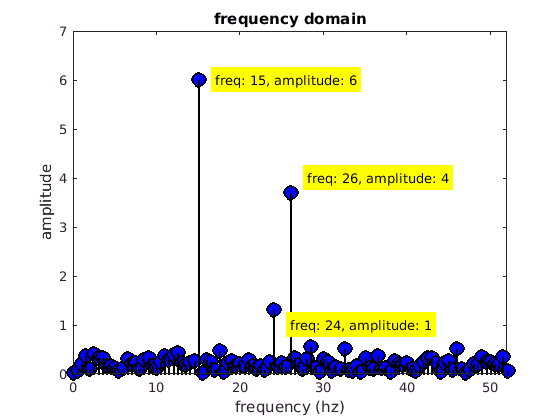

figure(2); clf;
stem(hz_vals, signal_amp(1:length(hz_vals)), 'ko', 'linew',2, 'markersize', 10, 'markerfacecolor', 'b');
set(gca, 'xlim', [0 max(freqs)*2]);
t1 = text(freqs(1)+2, amplitudes(1), str1, 'BackgroundColor', 'yellow');
t2 = text(freqs(2)+2, amplitudes(2), str2, 'BackgroundColor', 'yellow');
t3 = text(freqs(3)+2, amplitudes(3), str3, 'BackgroundColor', 'yellow');
xlabel("frequency (hz)");
ylabel("amplitude");
title("frequency domain");
hold off;

## Plot the inverse fft

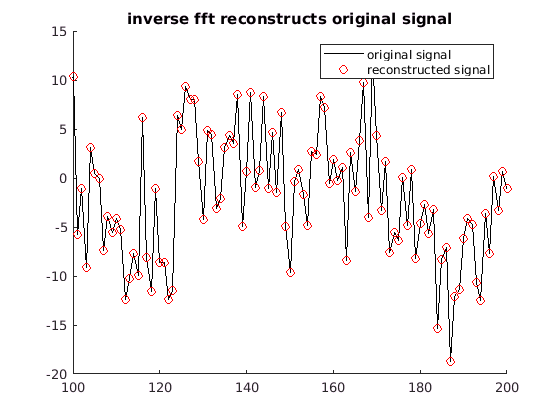

figure(3); clf;
hold on;
orig_plot = plot(noisy, 'k-');
inv_plot = plot(inv_signal, 'ro');
xlim([100 200]);
title("inverse fft reconstructs original signal");
legend(["original signal", "reconstructed signal"]);
hold off;